# Neural Network Classification 2

In this lab sheet we'll look at how to train and use a standard FeedForward network using built-in Matlab functions. Prerequisites:

- This script assumes you have completed the Matlab Fundamentals materials.

- It also builds upon the tasks7 activity.

## Loading and preparing datasets

Once we've loaded the data (which is novel), the following steps should all be familiar from the  k-NN lab. Refer back to it if you're not sure about any of the steps.

Read the digit dataset:

 % Locate the digit images 
digitDatasetPath = fullfile(matlabroot,'toolbox','nnet','nndemos', ...
    'nndatasets','DigitDataset');
% Load them into a image store. This includes labels etc.
imds = imageDatastore(digitDatasetPath, ...
    'IncludeSubfolders',true,'LabelSource','foldernames');
% We'll need the number of different labels for the network
numLabels = length(unique(sort(imds.Labels)));
% we will need the number of rows and columns of the images in the network
% Note that we can obtain any image by using its index
imageSize = size(readimage(imds,1));
% randomly split the dataset into two, 75% for training and 25% for Test 
rng(0);
[imdsTrain,imdsTest] = splitEachLabel(imds,0.75,'randomize');
% and the number of trainig and Test images:
numTrainImage = length(imdsTrain.Labels);
numTestImage = length(imdsTest.Labels);


% 2. convert the training images into a 2D matrix
train_params = zeros(numTrainImage,imageSize(1)*imageSize(2));
for i = 1 : numTrainImage
    train_params(i,:) = reshape(imdsTrain.read, imageSize(1)*imageSize(2), 1);
end

% 2a and the Test images
test_params = zeros(numTestImage, imageSize(1)*imageSize(2));
for i = 1 : numTestImage
    test_params(i,:) = reshape(imdsTest.read, imageSize(1)*imageSize(2), 1);
end



## Building a fully-connected net

Now set up a fully connected net with two layers, 25 and 20 nodes. We will use the test data to validate the model, checking to see if it has converged.


% Solution:

valid = cell(2,1);
valid{1} = test_params;
valid{2} = imdsTest.Labels;
net = fitcnet(valid{1},valid{2}, ...
    'LayerSizes',[25 20],...
    'Activations','sigmoid',...
    'Verbose',0, ...
    'ValidationData',valid)

net =   ClassificationNeuralNetwork
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [0    1    2    3    4    5    6    7    8    9]
           ScoreTransform: 'none'
          NumObservations: 2500
               LayerSizes: [25 20]
              Activations: 'sigmoid'
    OutputLayerActivation: 'softmax'
                   Solver: 'LBFGS'
          ConvergenceInfo: [1×1 struct]
          TrainingHistory: [1000×7 table]


  Properties, Methods



% 6. Get the prediced class memberships for the training and testing data
pred_train_labels = predict(net,train_params);
pred_test_labels = predict(net,test_params);
 
% 7. Get the confusion matrices
[confusion_train,~] = confusionmat(imdsTrain.Labels, pred_train_labels);
[confusion_test,~] = confusionmat(imdsTest.Labels, pred_test_labels);
% 
disp('Training accuracy');

Training accuracy


disp(sum(diag(confusion_train))/sum(sum(confusion_train))*100);

   69.2533




disp('Testing accuracy');

Testing accuracy


disp(sum(diag(confusion_test))/sum(sum(confusion_test))*100);

   85.9600



Now calculate the accuracy (I get 0.7519 and 0.7136)  respectively. Note that the results of Neural Nets are stochastic, so I can't garentee that you will get exeactly the same answer.  From the graphs see which numbers are confused with each other.

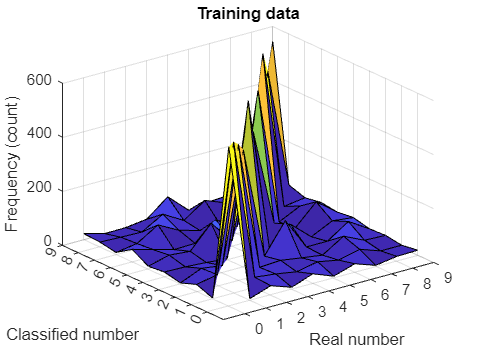

% 9. Plot some graphs
figure;
surf(confusion_train);
xticks([1 2 3 4 5 6 7 8 9 10]);
xticklabels([0 1 2 3 4 5 6 7 8 9]);
xlabel('Real number');
yticks([1 2 3 4 5 6 7 8 9 10]);
yticklabels([0 1 2 3 4 5 6 7 8 9]);
ylabel('Classified number');
zlabel('Frequency (count)');
title('Training data');

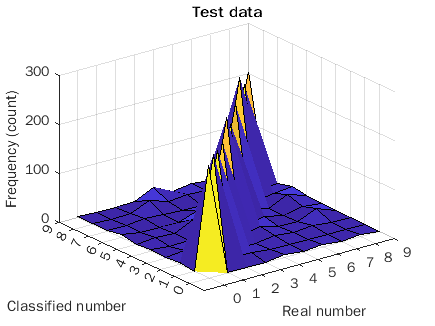


figure;
surf(confusion_test);
xticks([1 2 3 4 5 6 7 8 9 10]);
xticklabels([0 1 2 3 4 5 6 7 8 9]);
xlabel('Real number');
yticks([1 2 3 4 5 6 7 8 9 10]);
yticklabels([0 1 2 3 4 5 6 7 8 9]);
ylabel('Classified number');
zlabel('Frequency (count)');
title('Test data');

## Exploring  model size

Now write a function which will take a set of model hyper-parameters and return the best validation performance. Note that you can turn off the training window with a "Verbose." swtich, and that performance (validation loss) can be extracted from the net.TrainingHistory table. The latter will have a list of "ValidationChecks" - the number of iterations on which the validation loss increases before the current one. You need to find the loss for the iteration with the last 0 in this column as it is the best set of parameters. 

% Set up the values and test them
perform = zeros(3,3);
layer1 = [600 500 400];
layer2 = [15 20 25];

train_oneLabels = net.TrainingHistory.ValidationLoss;

for i = 1 : length(layer1)
    
    for j = 1 : length(layer2)
        
        % solution...
       

        perform(i,j) = train_MNISTnn([layer1(i) layer2(j)],train_params,train_oneLabels);
        disp([layer1(i) layer2(j) perform(i,j)]);
        
    end
    
end

  600.0000   15.0000    0.0600

  600.0000   20.0000    0.0600

  600.0000   25.0000    0.0600

  500.0000   15.0000    0.0645

  500.0000   20.0000    0.0645

  500.0000   25.0000    0.0645

  400.0000   15.0000    0.0715

  400.0000   20.0000    0.0715

  400.0000   25.0000    0.0715



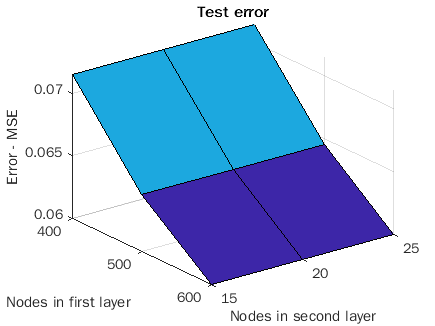




% 6. Plot the accuracy
figure;
surf(perform);
xticks(1 : length(layer2));
xticklabels(layer2);
xlabel('Nodes in second layer');
yticks(1 : length(layer1));
yticklabels(layer1);
ylabel('Nodes in first layer');
zlabel('Error - MSE');
title('Test error');


% Find the parameters associated with the lowest error:

[p1,p2] = find(perform==min(min(perform)));
disp(layer1(p1.')); 

   600   600   600



disp(layer2(p2.'));

    15    20    25



disp([perform(p1,p2)]);

    0.0600    0.0600    0.0600
    0.0600    0.0600    0.0600
    0.0600    0.0600    0.0600




n1 = mean(layer1(p1.'))

n1 = 600

n2 = mean(layer2(p2.'))

n2 = 20

Now build a model with the best pair of layers and get the test-data accuracy (mine has [ 500 20 ] as the layer-sizes) :


valid = cell(2,1);
valid{1} = test_params;
valid{2} = imdsTest.Labels;
net = fitcnet(valid{1},valid{2}, ...
    'LayerSizes',[n1 n2],...
    'Activations','sigmoid',...
    'Verbose',0)

net =   ClassificationNeuralNetwork
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [0    1    2    3    4    5    6    7    8    9]
           ScoreTransform: 'none'
          NumObservations: 2500
               LayerSizes: [600 20]
              Activations: 'sigmoid'
    OutputLayerActivation: 'softmax'
                   Solver: 'LBFGS'
          ConvergenceInfo: [1×1 struct]
          TrainingHistory: [630×7 table]


  Properties, Methods



% 6. Get the prediced class memberships for the training and testing data
pred_train_labels = predict(net,train_params);
pred_test_labels = predict(net,test_params);
 
% 7. Get the confusion matrices
[confusion_train,~] = confusionmat(imdsTrain.Labels, pred_train_labels);
[confusion_test,~] = confusionmat(imdsTest.Labels, pred_test_labels);

disp('Training accuracy');

Training accuracy


disp(sum(diag(confusion_train))/sum(sum(confusion_train))*100);

   87.6400




disp('Testing accuracy');

Testing accuracy


disp(sum(diag(confusion_test))/sum(sum(confusion_test))*100);

   100



## Comparing with CNN

Now consider a CNN on the same data:

% first the training options  
options = trainingOptions('sgdm', ...
    'MaxEpochs',16, ...
    'InitialLearnRate',0.005, ...
    'ValidationData',imdsTest,...
    'ValidationFrequency',10,...
    'ValidationPatience',2, ...
    'Verbose',true, ...
    'VerboseFrequency',30, ...
    'Plots','training-progress',...
    'ExecutionEnvironment', 'auto');

% then set the model up...
        layers = [
            imageInputLayer([imageSize 1])
            convolution2dLayer(3,15,'Padding',1)
            batchNormalizationLayer
            reluLayer
            maxPooling2dLayer(2,'Stride',2)
            convolution2dLayer(5,20,'Padding',2)
            batchNormalizationLayer
            reluLayer
            fullyConnectedLayer(15)
            fullyConnectedLayer(numLabels)
            softmaxLayer
            classificationLayer];
% Actually train it
[net3,info] = trainNetwork(imdsTrain,layers,options);

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:06 |        7.81% |       15.08% |       2.7775 |       2.5077 |          0.0050 |
|       1 |          10 |       00:00:07 |       33.59% |       37.72% |       1.9545 |       1.7374 |          0.0050 |
|       1 |          20 |       00:00:08 |       50.00% |       55.88% |       1.4200 |       1.2981 |          0.0050 |
|       1 |          30 |       00:00:09 |       67.97% |       67.40% |       0.9528 |   

Now get the accuracy:

% Now use the network to infer the labels of the training images
pred3_train_labels = classify(net3,imdsTrain);
% and also of the validation set
pred3_test_labels = classify(net3,imdsTest);
% Obtain a confusion matrix of the labels (i.e. the counts of each
% (inferred,real) label combination for the two datasets
[confusion3_train,order_train] = confusionmat(imdsTrain.Labels, pred3_train_labels);
[confusion3_test,order_test] = confusionmat(imdsTest.Labels, pred3_test_labels);
% And finally display the accuracy of the classifier (i.e. the fraction of
% images which are correctly labeled by the net.
disp('Training accuracy : ');

Training accuracy : 


disp(sum(diag(confusion3_train))/sum(sum(confusion3_train))* 100) ;

   99.9867



disp('Training accuracy : ');

Training accuracy : 


disp(sum(diag(confusion3_test))/sum(sum(confusion3_test))* 100) ;

   99.7200



## Varying the CNN

Now build another convolutional net from the data, this one with a third convolutional layer. Make the new layer have 20 7-by-7 pixel kernels. Note that you'll have to change the padding size as well. Investigate its accuracy - I get 1.0 and 0.9976 (note that I haven't sort to tune the 3rd layer).

layers = [
    imageInputLayer([imageSize 1])

    convolution2dLayer(3,15,'Padding',1)
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(3,'Stride',3)

    convolution2dLayer(5,20,'Padding',2)
    batchNormalizationLayer
    reluLayer

    convolution2dLayer(20,7,'Padding',7)
    batchNormalizationLayer
    reluLayer


    fullyConnectedLayer(15)
    fullyConnectedLayer(numLabels)
    softmaxLayer
    classificationLayer];

[net3,info] = trainNetwork(imdsTrain,layers,options);

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:06 |        4.69% |       12.00% |       2.7684 |       2.5150 |          0.0050 |
|       1 |          10 |       00:00:07 |       39.06% |       44.00% |       1.7660 |       1.6927 |          0.0050 |
|       1 |          20 |       00:00:07 |       65.62% |       55.60% |       1.3553 |       1.3990 |          0.0050 |
|       1 |          30 |       00:00:08 |       67.97% |       63.92% |       1.0749 |   


pred3_train_labels = classify(net3,imdsTrain);
% and also of the validation set
pred3_test_labels = classify(net3,imdsTest);

% Obtain a confusion matrix of the labels (i.e. the counts of each
% (inferred,real) label combination for the two datasets

[confusion3_train,order_train] = confusionmat(imdsTrain.Labels, pred3_train_labels);
[confusion3_test,order_test] = confusionmat(imdsTest.Labels, pred3_test_labels);

% And finally display the accuracy of the classifier (i.e. the fraction of
% images which are correctly labeled by the net.
disp('Training accuracy : ');

Training accuracy : 


disp(sum(diag(confusion3_train))/sum(sum(confusion3_train))* 100) ;

   100



disp('Training accuracy : ');

Training accuracy : 


disp(sum(diag(confusion3_test))/sum(sum(confusion3_test))* 100) ;

   99.8000

